## Q1

Plant ID = 62132    Arbor Hill Wind Farm

Longitude = -94.261358

Latitude = 41.404231

Wind Turbine Model = Vestas V110-2.0

Hub Height = 95.0976m, 312ft

## Q2

% read files
plantcode = 62132; % Arbor Hill Wind Farm

data = readtable('/Users/yashr/Library/CloudStorage/OneDrive-ImperialCollegeLondon/Year 4/SES/Yash_Runghoo_02276750.csv'); %CSV file containing hourly wind speeds from https://www.renewables.ninja
time = data.time;                  % datetime or numeric
windSpeed = data.("wind_speed");           % wind speed in m/s

% parameters
rho = 1.225;        % Air density [kg/m^3]
D = 110;           % Rotor diameter [m]
A = pi*(D/2)^2;    % Rotor swept area [m^2]

Pr = 2.0;          % Rated turbine power [MW]
v_ci = 4;          % Cut-in speed [m/s]
v_r = 12;         % Rated speed [m/s]
v_co = 20;         % Cut-out speed [m/s]


Parameters were taken from the [https://www.thewindpower.net/turbine_en_590_vestas_v110-2000.php](https://www.thewindpower.net/turbine_en_590_vestas_v110-2000.php) for my specified model

% Rated power divided by the maximum power at the rated wind speed gives
% the total efficiency of the wind turbine.

eta_total = Pr*10^6 / (0.5 * rho * A * (v_r)^3); % total efficiency of wind turbine, gearbox, generator

% This function computes the hourly electrical power of a turbine.
% Assumptions:
% Cubic power law between cut-in speed (v_ci) and rated speed (v_r)
% Power is capped at rated power (Pr) between rated speed and cut-out speed
% (v_co), as pitch control limits power
% Zero power below cut-in speed or above cut-out speed. 0 above cut-out, to
% avoid structural damage. 0 below cut in, as this is the minimum 
% wind speed required for power generation

function [P, P_cubic_region, P_max_region] = calcWindPower(v, rho, A, Pr, v_ci, v_r, v_co, eta_total)
    P = zeros(size(v));               % total power array
    P_max_region = zeros(size(v));    % rated power region array
    P_cubic_region = zeros(size(v));  % cubic region array
    
    for i = 1:length(v)
        if v(i) < v_ci
            % Below cut-in: no power
            P(i) = 0;
            P_max_region(i) = 0;
            P_cubic_region(i) = 0;
        elseif v(i) < v_r
            % Cubic region: power increases ^3
            Pa = 0.5 * rho * A * v(i)^3 / 1e6;   % aerodynamic power [MW]
            P(i) = eta_total * Pa;
            P_cubic_region(i) = eta_total * Pa;
            P_max_region(i) = 0;
        elseif v(i) <= v_co
            % Rated region: constant power (pitch-controlled)
            P(i) = Pr;
            P_max_region(i) = Pr;
            P_cubic_region(i) = 0;
        else
            % Above cut-out: turbine shuts down
            P(i) = 0;
            P_max_region(i) = 0;
            P_cubic_region(i) = 0;
        end
    end
end

[P, P_cubic_region, P_max_region] = calcWindPower(windSpeed, rho, A, Pr, v_ci, v_r, v_co, eta_total);
annualEnergy_MWh = sum(P); % Total energy produced by one turbine in MWh
CF_modelled = annualEnergy_MWh / (Pr*8760); % Capacity factor for one turbine

fprintf('Power output outside the maximum power region for one turbine: %.3f MWh \n', sum(P_cubic_region));

Power output outside the maximum power region for one turbine: 4451.726 MWh 


fprintf('Power output inside the maximum power region for one turbine: %.3f MWh\n', sum(P_max_region));

Power output inside the maximum power region for one turbine: 1494.000 MWh


fprintf('Modelled capacity factor: %.3f\n', CF_modelled);

Modelled capacity factor: 0.339


## Q3

%load EIA923 data
filename = "/Users/yashr/Library/CloudStorage/OneDrive-ImperialCollegeLondon/Year 4/SES/f923_2019/EIA923_Schedules_2_3_4_5_M_12_2019_Final_Revision.xlsx";
opts = detectImportOptions(filename);
opts.DataRange = "A7";
opts.VariableNamesRange = "A6:CS6";
data_actual = readtable(filename, opts);

idx = data_actual.("PlantId") == plantcode;
plantRowData = data_actual(idx, :);

% load turbine data
turbine_data = readtable("/Users/yashr/Library/CloudStorage/OneDrive-ImperialCollegeLondon/Year 4/SES/eia8602023/3_2_Wind_Y2023.xlsx");

idx1 = turbine_data.("PlantCode") == plantcode & turbine_data.("OperatingYear") <= 2019;
turbine_plant_row = turbine_data(idx1, :);

% calculate actual capacity factor
actualGeneration_MWh = plantRowData.("NetGeneration_Megawatthours_");
Pr_farm = Pr * turbine_plant_row.("NumberOfTurbines"); % (MW) rated power * number of turbines
CF_actual = actualGeneration_MWh / (Pr_farm * 8760);
fprintf('Observed capacity factor: %.3f\n', CF_actual);

Observed capacity factor: 0.387


Here we can see that the observed capacity factor is larger than the modelled capacity factor of the turbine. Although we might expect the modelled capacity factor to be higher (since it doesn’t account for wake losses or downtime), it is lower in this case. The main reasons are:

- The model simulates only one turbine, while the observed capacity factor includes all turbines on the farm.

- The model assumes the same wind speed at all turbines, whereas in reality wind speeds vary across the site due to terrain and microclimate effects. Some turbines may operate closer to their rated speed more often.

- The farm may include turbines with slightly different power curves or efficiencies than the predominant Vestas V110-2.0 model, contributing to higher overall energy production.

- Renewables ninja uses MERRA-2 reanalysed data which is spatially averaged, and due to the cubic power law, this can underestimate energy production. Short periods of high wind speed can disproportionately affect energu

## Q4

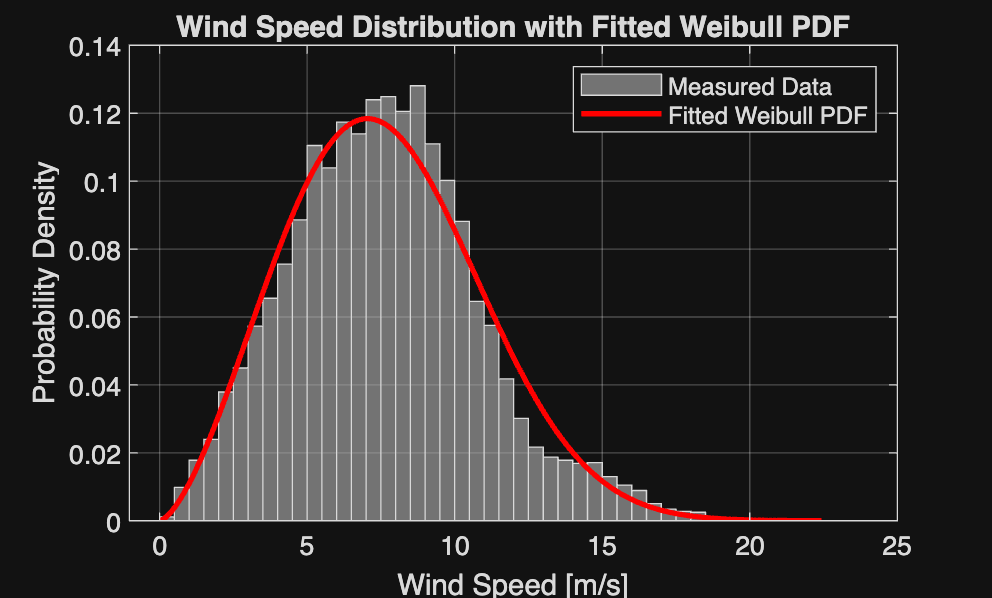


% Clean wind speed data
v_clean = windSpeed(~isnan(windSpeed) & windSpeed>0);

% Fit Weibull to measured data
weibullParams = wblfit(v_clean);        % Maximum likelihood fit
A_weibull = weibullParams(1);           % scale parameter (A), characteristic wind speed
k_weibull = weibullParams(2);           % shape parameter (K), variability of the wind

% Compute Weibull PDF
windSpeed_vals = linspace(0, max(v_clean)+2, 500);   % wind speed range
f_pdf = (k_weibull/A_weibull) * (windSpeed_vals/A_weibull).^(k_weibull-1) ...
        .* exp(-(windSpeed_vals/A_weibull).^k_weibull);

% Plot histogram of measured data (normalized to PDF)
figure;
histogram(v_clean, 'Normalization', 'pdf', 'FaceColor', [0.7 0.7 0.7]); % measured data
hold on;
plot(windSpeed_vals, f_pdf, 'r-', 'LineWidth', 2);  % fitted Weibull
xlabel('Wind Speed [m/s]');
ylabel('Probability Density');
title('Wind Speed Distribution with Fitted Weibull PDF');
legend('Measured Data', 'Fitted Weibull PDF');
grid on;


% Compute hours at rated capacity
P_rated_fraction = exp(-(v_r/A_weibull)^k_weibull) ...
                 - exp(-(v_co/A_weibull)^k_weibull);  % fraction of time wind >= rated
hours_rated = P_rated_fraction * 8760;  % rated hours per year per turbine

fprintf('Estimated hours at rated capacity per turbine: %.0f hours/year\n', hours_rated);

Estimated hours at rated capacity per turbine: 860 hours/year


## Q5

Pr_levels = 1.9:0.1:5.0;  % MW
E_annual_levels = zeros(size(Pr_levels));
CF_levels = zeros(size(Pr_levels));
delta_E_levels = zeros(size(Pr_levels));         % increase in GWh
E_annual_levels_GWh = zeros(size(Pr_levels));    % annual energy in GWh

% Base annual energy for comparison
E_base = sum(calcWindPower(windSpeed, rho, A, Pr, v_ci, v_r, v_co, eta_total));  % MWh

fprintf('\n Calculations done for all %.0f turbines\n', turbine_plant_row.("NumberOfTurbines"));


 Calculations done for all 125 turbines



for j = 1:length(Pr_levels)
    % Compute new rated speed for this rated power by working backwards
    % from efficiency and rated power, to get the rated wind speed
    v_r_new = (Pr_levels(j)*1e6 / (0.5 * rho * A * eta_total))^(1/3);

    % Compute power time series with new rated power and rated speed
    P_new = calcWindPower(windSpeed, rho, A, Pr_levels(j), v_ci, v_r_new, v_co, eta_total);

    % Annual energy & capacity factor
    E_annual_levels(j) = sum(P_new); % energy for 1 turbine
    CF_levels(j) = E_annual_levels(j) / (Pr_levels(j)*8760);  
    delta_E_levels(j) = (E_annual_levels(j) - E_base)/1000;  % GWh increase
    E_annual_levels_GWh(j) = (E_annual_levels(j) * turbine_plant_row.("NumberOfTurbines")) /1000;        % Convert MWh to GWh

    % Print results
    fprintf('Pr = %.1f MW, v_r_new = %.2f m/s, CF = %.3f, Annual energy = %.2f GWh\n',...
            Pr_levels(j), v_r_new, CF_levels(j), E_annual_levels_GWh(j));
end

Pr = 1.9 MW, v_r_new = 11.80 m/s, CF = 0.353, Annual energy = 733.47 GWh
Pr = 2.0 MW, v_r_new = 12.00 m/s, CF = 0.339, Annual energy = 743.22 GWh
Pr = 2.1 MW, v_r_new = 12.20 m/s, CF = 0.327, Annual energy = 752.12 GWh
Pr = 2.2 MW, v_r_new = 12.39 m/s, CF = 0.316, Annual energy = 760.45 GWh
Pr = 2.3 MW, v_r_new = 12.57 m/s, CF = 0.305, Annual energy = 768.22 GWh
Pr = 2.4 MW, v_r_new = 12.75 m/s, CF = 0.295, Annual energy = 775.49 GWh
Pr = 2.5 MW, v_r_new = 12.93 m/s, CF = 0.286, Annual energy = 782.43 GWh
Pr = 2.6 MW, v_r_new = 13.10 m/s, CF = 0.277, Annual energy = 788.90 GWh
Pr = 2.7 MW, v_r_new = 13.26 m/s, CF = 0.269, Annual energy = 795.07 GWh
Pr = 2.8 MW, v_r_new = 13.42 m/s, CF = 0.261, Annual energy = 800.91 GWh
Pr = 2.9 MW, v_r_new = 13.58 m/s, CF = 0.254, Annual energy = 806.38 GWh
Pr = 3.0 MW, v_r_new = 13.74 m/s, CF = 0.247, Annual energy = 811.55 GWh
Pr = 3.1 MW, v_r_new = 13.89 m/s, CF = 0.241, Annual energy = 816.38 GWh
Pr = 3.2 MW, v_r_new = 14.04 m/s, CF = 0.234, Annua

Advantages

- Higher annual energy output due to increased rated power.

- Turbine produces more power in the rated region when it reaches it, due to the higher capacity.

Disadvantages

- The rated power region becomes smaller, requiring higher wind speeds to reach full output.

- Rated wind speed increases, so the turbine spends less time at maximum power.

- Capacity factor decreases, indicating lower overall efficiency relative to rated power.

This is all assuming that the cut-in and cut-out speeds don't change.

**Advantages**

- Increased rated capacity raises the maximum electrical output when high wind speeds occur.

- Some increase in annual energy production occurs because power is no longer clipped at the original rated limit during high-wind periods.

- Better utilisation of strong wind events that were previously cutoff by generator limits.

**Disadvantages**

- Rotor swept area is unchanged, so the aerodynamic power available in the wind is unchanged.

- Increasing rated power forces the rated wind speed to increase.

- High wind speeds occur infrequently (wind speeds follow a Weibull distribution), so the turbine reaches rated output less often.

- The turbine therefore operates mostly outside the maximum power region rather than in the rated region.

- Capacity factor decreases because the installed capacity increases faster than annual energy production.

- Annual energy gain shows diminishing returns, large increases in rated capacity produce only small increases in AEP.

- Less suitable for moderate-wind sites. Benefits mainly appears in high-wind regimes.

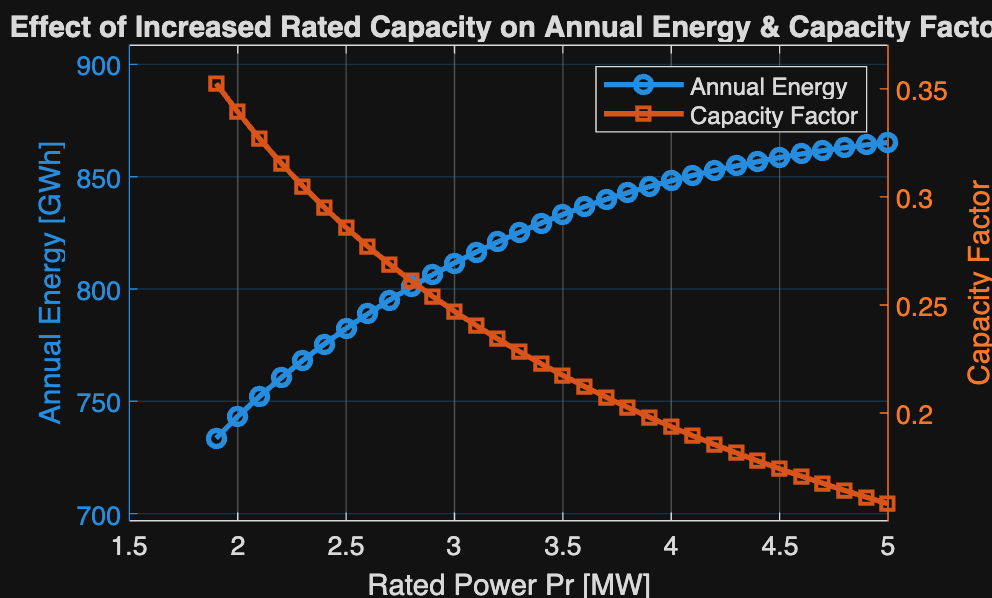

% Plot annual energy and capacity factor vs rated power
figure;
yyaxis left
plot(Pr_levels, E_annual_levels_GWh, '-o', 'LineWidth', 2, 'MarkerSize', 6);
ylabel('Annual Energy [GWh]');
ylim([min(E_annual_levels_GWh)*0.95, max(E_annual_levels_GWh)*1.05]);

yyaxis right
plot(Pr_levels, CF_levels, '-s', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.85 0.33 0.1]);
ylabel('Capacity Factor');
ylim([min(CF_levels)*0.95, max(CF_levels)*1.05]);

xlabel('Rated Power Pr [MW]');
title('Effect of Increased Rated Capacity on Annual Energy & Capacity Factor');
grid on;
legend('Annual Energy', 'Capacity Factor', 'Location', 'northeast');